close all;
clearvars -except unnamed;

activity = 0.5; %1.6 for LiClO4, 1.9 for LiPF6 in EMC/EC (0.02,0.11,7.6 for clyte diff) 1 for EMC solvent              

% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'LCO_LiPF6_Li05.csv','LCO_LiPF6_Li06.csv','LCO_LiPF6_Li07.csv','LCO_LiPF6_Li08.csv'};
% 
temp_vec = [293,293];   
conc_vec = [0.35,0.4];
filenames = {'./c_035.csv','./c_040.csv'};

% Load files
% Change filenames here
% temp_vec = [293,308,318]; %Temperature values
% conc_vec = [0.5,0.5,0.5]; %Concentration values
% filenames = {'LCO_Li05.csv',...
%     'LCO_LiClO4_T_dependent_35C.csv','LCO_LiClO4_T_dependent_45C.csv'}; %Corresponding filenames
% 
% temp_vec = [293,293,293,293,308,318]; %Temperature values
% conc_vec = [0.5,0.6,0.7,0.8,0.5,0.5]; %Concentration values
% filenames = {'LCO_Li05.csv','LCO_Li06.csv','LCO_Li07.csv','LCO_Li08.csv','LCO_LiClO4_T_dependent_35C.csv'...
%     'LCO_LiClO4_T_dependent_45C.csv'}; %Corresponding filenames

% temp_vec = [293,293,293,293]; %Temperature values
% conc_vec = [0.5,0.6,0.7,0.8]; %Concentration values
% filenames = {'LCO3_Li05.csv','LCO3_Li06.csv','LCO3_Li07.csv','LCO3_Li08.csv'}; %Corresponding filenames

% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'NMC_Li05.csv','NMC_Li06.csv','NMC_Li07.csv','NMC_Li08.csv'};

% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'NMC2_Li05.csv','NMC2_Li06.csv','NMC2_Li07.csv','NMC2_Li08.csv'};
% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'NMC3_Li05.csv','NMC3_Li06.csv','NMC3_Li07.csv','NMC3_Li08.csv'};
% 
% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'NMC_LiPF6_Li05.csv','NMC_LiPF6_Li06.csv','NMC_LiPF6_Li07.csv','NMC_LiPF6_Li08.csv'};

% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'NMC3_LiPF6_Li05.csv','NMC3_LiPF6_Li06.csv','NMC3_LiPF6_Li07.csv','NMC3_LiPF6_Li08.csv'};

% temp_vec = [293,293,293,293];
% conc_vec = [0.5,0.6,0.7,0.8];
% filenames = {'LCO3_LiPF6_Li05.csv','LCO3_LiPF6_Li06.csv','LCO3_LiPF6_Li07.csv','LCO3_LiPF6_Li08.csv'};

% temp_vec = [293,293,293];
% conc_vec = [0.6,0.7,0.8];
% filenames = {'811_Li06.csv','811_Li07.csv','811_Li08.csv'};

% temp_vec = [293];
% conc_vec = [0.5];
% filenames = {'LCO_0.02M.csv'};


% temp_vec = [293];
% conc_vec = [0.5];
% filenames = {'LCO_EMC_LiPF6_1M.csv'};

% temp_vec = [298,308,318];
% conc_vec = [0.5,0.5,0.5];
% filenames = {'LCO_LiClO4_T_25C.csv','LCO_LiClO4_T_35C.csv','LCO_LiClO4_T_45C.csv'};

% temp_vec = [293,293];
% conc_vec = [0.3,0.4];
% filenames = {'graphite_Li03.csv','graphite_Li04.csv'};

Num_temps = size(temp_vec,2);

% rxn_types = {'ICET_symmetric','ICET_asymmetric','ECIT_normal','ECIT_normal2',...
%     'uniformly_valid','uniformly_valid2','ICET_symmetric_film','ICET_asymmetric_film'};
%Tradeoff in ECIT between maintaining slope and linearity causes a lmbda to
%be optimal but it is out of ECIT limit
%rxn_types = {'BV'}
%rxn_types = {'ICET_asymmetric_film2'};
%rxn_types = {'ECIT_normal2'};
rxn_types = {'ECIT_normal2'}

rxn_types = 1×1 cell array
    {'ECIT_normal2'}


legend_names = {'ICET'};

Slope Values : \n
    0.0024
    0.0023


GlobalSearch stopped because it analyzed all the trial points.

All 5 local solver runs converged with a positive local solver exit flag.
k0 : 
 -9624.15 
lambda : 
    4.07 
dG_IT : 
   12.13 
w_ads : 
    0.50 


   1.0e-03 *

    0.2055
    0.2039
    0.2022
    0.2004
    0.1986
    0.1966
    0.1945
    0.1924
    0.1901
    0.1877
    0.1852
    0.1826
    0.1799
    0.1771
    0.1742
    0.1712
    0.1681
    0.1649
    0.1615
    0.1581
    0.1546
    0.1510
    0.1473
    0.1435
    0.1396
    0.1357
    0.1316
    0.1276
    0.1234
    0.1192
    0.1150
    0.1108
    0.1065
    0.1022
    0.0978
    0.0935
    0.0892
    0.0849
    0.0807
    0.0765
    0.0723
    0.0682
    0.0642
    0.0602
    0.0564
    0.0526
    0.0490
    0.0455
    0.0422
    0.0390
    0.0360
    0.0332
    0.0306
    0.0282
    0.0261
    0.0242
    0.0226
    0.0213
    0.0202
    0.0194
    0.0188
    0.0184
    0.0183
    0.0182
    0.0182
    0.0183
    0.0184
    0.0185
    0.0186
    0.0186
    0.0186
    0.0185
    0.0183
    0.0181
    0.0178
    0.0174
    0.0169
    0.0164
    0.0158
    0.0151
    0.0144
    0.0137
    0.0129
    0.0121
    0.0113
    0.0104
    0.0096
    0.0087
    0.0079
    0.0


 ICET BIC:-30657.48827 



 ICET Chi-squared:NaN 


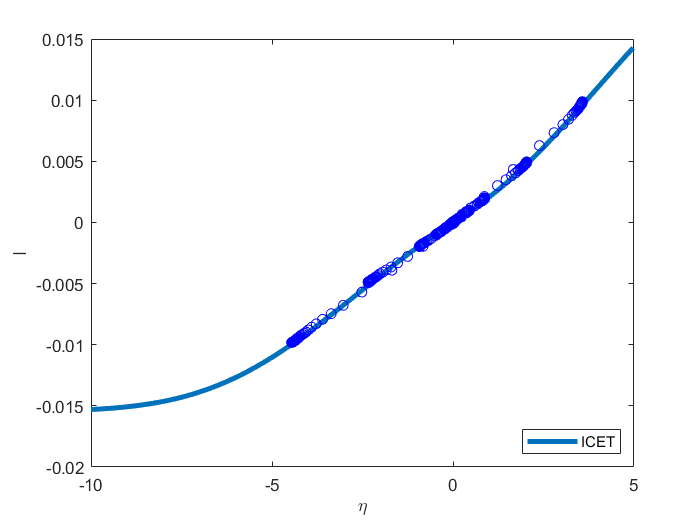

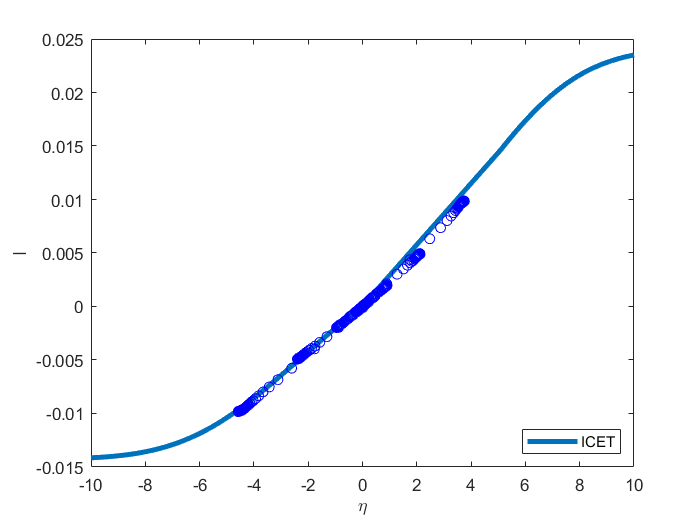

for j=1:size(rxn_types,2)
[f_fit,bounds,tht_fit,cost_val,chi_squared,BIC,size_vec,xdata,ydata,xvalues] = get_fit_2(temp_vec,conc_vec,filenames,rxn_types{j},activity);
disp(bounds)
fprintf('\n %s BIC:%0.5f \n',legend_names{j},BIC);
fprintf('\n %s Chi-squared:%0.5f \n',legend_names{j},chi_squared);
size_vec_2 = 150*ones(size(filenames,2),1);
figure(1);
set(findall(gcf,'-property','FontSize'),'FontSize',32);
[X_vals,idx] = sort(xvalues(1:size_vec_2(1)));
[X_vals2,idx2] = sort(xdata(1:size_vec(1)));
Y_vals = f_fit(1:size_vec_2(1))+bounds(1:size_vec_2(1));
plot(X_vals,(Y_vals(idx)),'LineWidth',3);
hold on;
if j == size(rxn_types,2)
    Ydata = ydata(1:size_vec(1));
    plot(X_vals2,Ydata(idx2),'bo');
    xlabel('${\eta}$','Interpreter',"latex");
    ylabel('I');
    legend(legend_names,"Location","southeast");
end
for i=2:Num_temps
figure(i);
set(findall(gcf,'-property','FontSize'),'FontSize',32);
S = sum(size_vec(1:i-1),'all');
S2 = sum(size_vec_2(1:i-1),'all');
[X_vals,idx] = sort(xvalues(S2+1:S2+size_vec_2(i)));
[X_vals2,idx2] = sort(xdata(S+1:S+size_vec(i)));
Y_vals = f_fit(S2+1:S2+size_vec_2(i)) + bounds(S2+1:S2+size_vec_2(i));
plot(X_vals,(Y_vals(idx)),'LineWidth',3);
hold on;
if j == size(rxn_types,2)
    Ydata = ydata(S+1:S+size_vec(i));
    plot(X_vals2,Ydata(idx2),'bo');
    xlabel('${\eta}$','Interpreter',"latex");
    ylabel('I');
    legend(legend_names,"Location","southeast");
end
end
end

% for j=1:size(rxn_types,2)
% [f_fit,tht_fit,cost_val,BIC,size_vec,xdata,ydata] = get_fit_2(temp_vec,conc_vec,filenames,rxn_types{j});
% fprintf('\n %s BIC:%0.5f \n',legend_names{j},BIC);
% fprintf('\n %s Cost:%0.5f \n',legend_names{j},cost_val);
% figure(1);
% set(findall(gcf,'-property','FontSize'),'FontSize',24)
% [X_vals,idx] = sort(xdata(1:size_vec(1)));
% Y_vals = f_fit(1:size_vec(1));
% semilogy(X_vals,abs(Y_vals(idx))./tht_fit(1),'LineWidth',3);
% hold on;
% if j == size(rxn_types,2)
%     xlabel('${\eta}$','Interpreter',"latex");
%     ylabel('I/k0');
%     legend(legend_names,"Location","southeast");
% end
% for i=2:Num_temps
% figure(i);
% set(findall(gcf,'-property','FontSize'),'FontSize',24)
% S = sum(size_vec(1:i-1),'all');
% [X_vals,idx] = sort(xdata(S+1:S+size_vec(i)));
% Y_vals = f_fit(S+1:S+size_vec(i));
% semilogy(X_vals,abs(Y_vals(idx))./tht_fit(1),'LineWidth',3);
% hold on;
% if j == size(rxn_types,2)
%     xlabel('${\eta}$','Interpreter',"latex");
%     ylabel('I/k0');
%     legend(legend_names,"Location","southeast");
% end
% end
% end